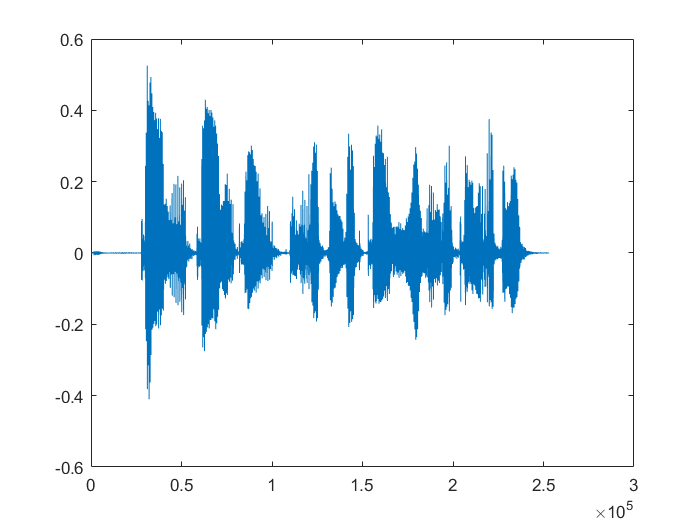

[Sig, fs] = audioread("Final - Mono.wav");
plot(Sig)

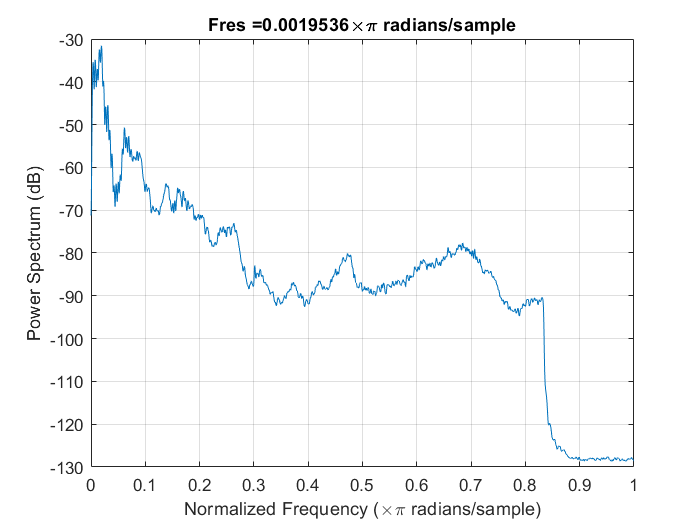

pspectrum(Sig)

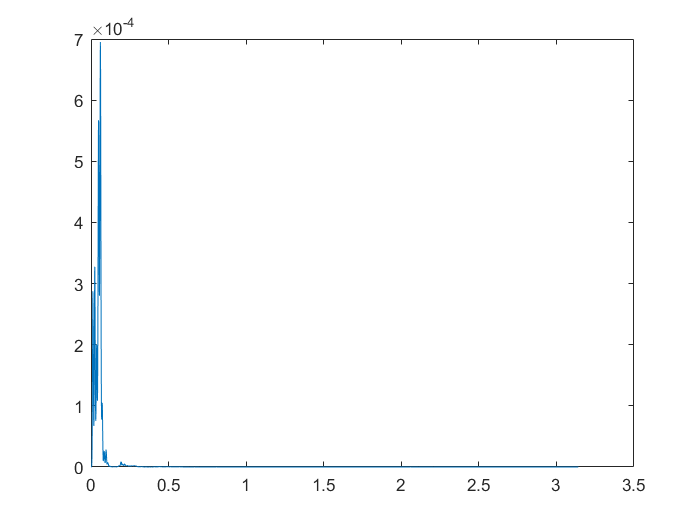

[p,f] = pspectrum(Sig);
plot(f, p)

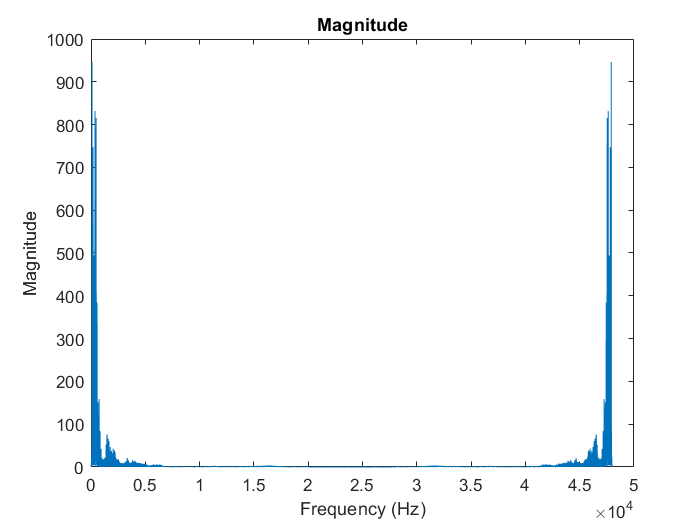

SigFt = fft(Sig);
f = (0:length(SigFt)-1)*fs/length(SigFt);
plot(f,abs(SigFt))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')

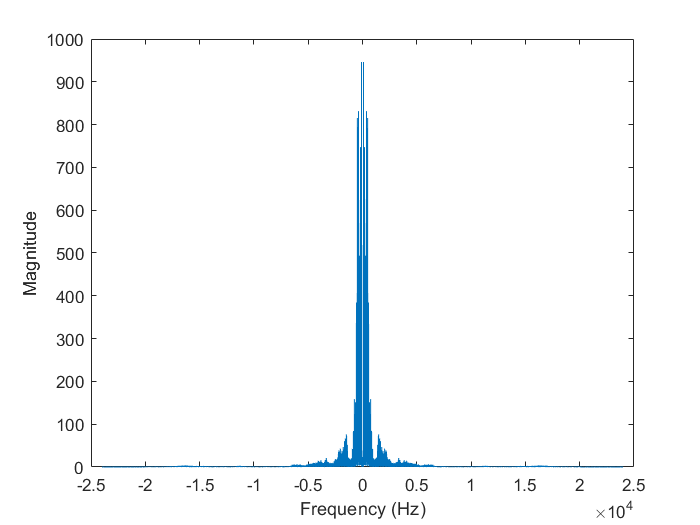

n = length(Sig);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(SigFt);
plot(fshift,abs(yshift))
xlabel('Frequency (Hz)')
ylabel('Magnitude')

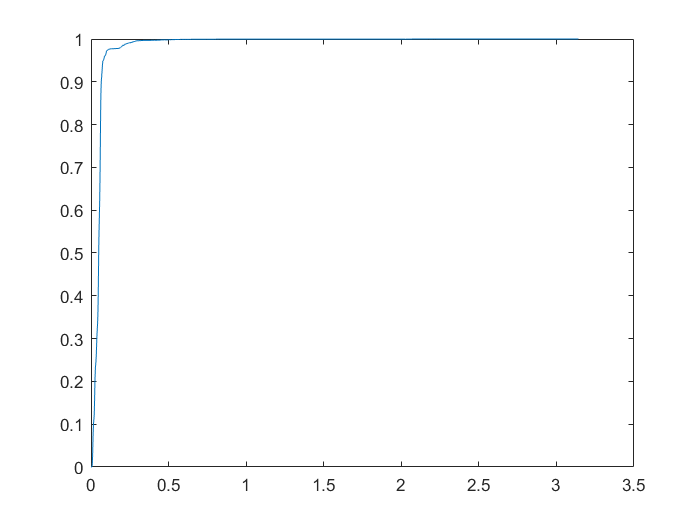

[p,f] = pspectrum(Sig);
cp = cumsum(p);
cpn = cp/cp(end);
plot(f, cpn)

fc = (0.066)*(10^4)

fc = 660

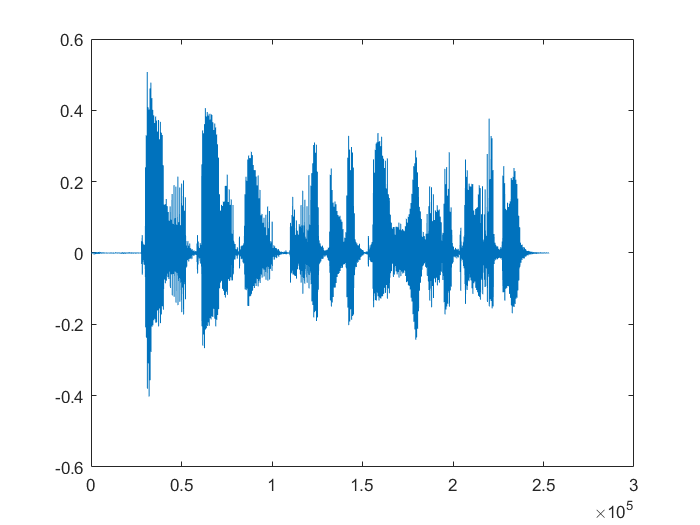

filtered = lowpass(Sig, 660, fs);
plot(filtered)

sound(filtered, fs)

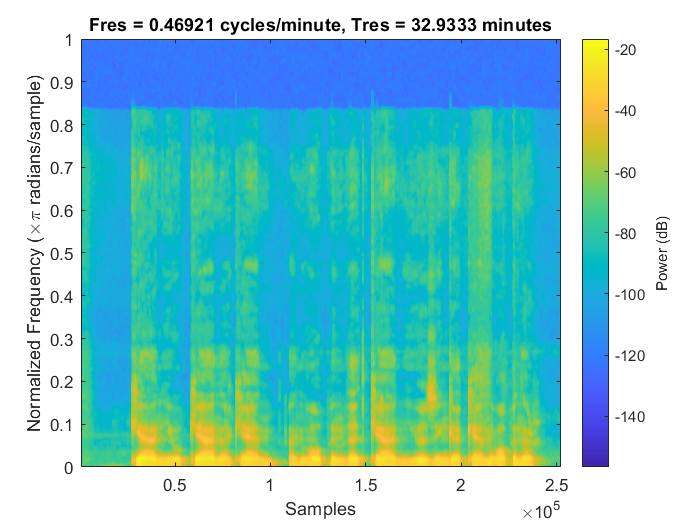

pspectrum(Sig, "spectrogram")

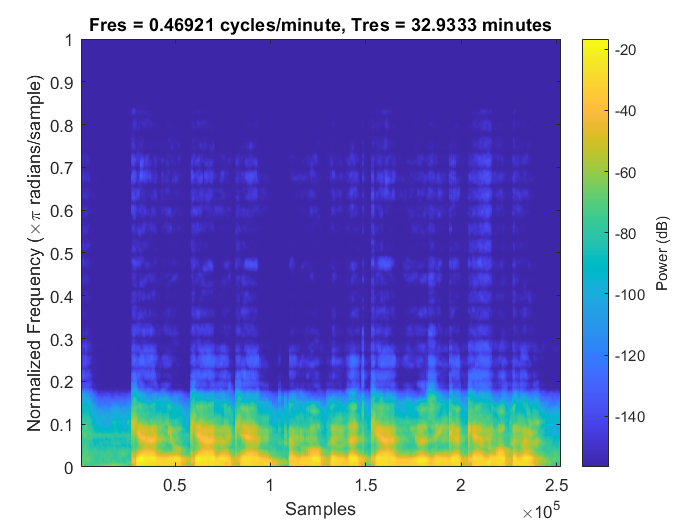

pspectrum(filtered, "spectrogram")

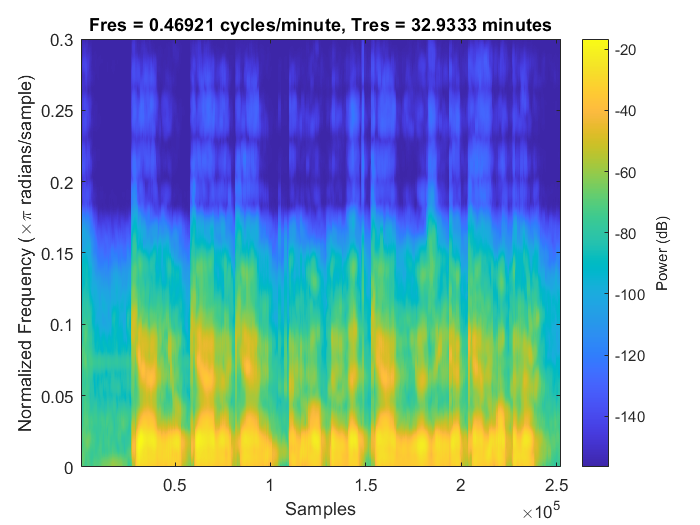

pspectrum(filtered, "spectrogram", "FrequencyLimits", [0 0.3*pi])